# Pb11 - Suplimentar

- Calculam seria Taylor trunchiata:

                                    
$$T_N \left(x\right)=\sum_{n=0}^N \frac{f^{\left(x\right)} \left(a\right)}{n!}{\left(x-a\right)}^n$$


         2. Calculam derivata de ordin N+1

                                    
$$f^{\left(N+1\right)} \left(x\right)$$


        3. Evaluam aceasta derivata intr-un punct intermediar 

                                ξ=a+θ(x−a), unde θ≈1/2

        4. Aplicam formula restului Lagrange

                                
$$R_N \left(x\right)=\frac{{\left(x-a\right)}^{N+1} *f^{\left(N+1\right)} \left(\xi \right)}{\left(N+1\right)!}$$


        5. Adaugam acest rest la seria Taylor pentru o aproximare mai buna

function T_taylor_lagrange = taylor_lagrange(f, a, N)

    syms x theta;
    
    % seria Taylor trunchiată
    T_taylor = taylor(f, x, 'ExpansionPoint', a, 'Order', N+1);
    
    % restul Lagrange
    f_deriv = diff(f, x, N+1);
    
    % Alegem xi conform formulei restului (xi = a + θ(x - a))
    xi = a + theta * (x - a);
    
    % Evaluăm derivata în xi
    f_deriv_xi = subs(f_deriv, x, xi);
    
    % Aplicăm formula restului Lagrange:
    R_N = ( (x - a)^(N+1) / factorial(N+1) ) * f_deriv_xi;
    
    % adăugăm restul la seria Taylor trunchiată
    T_taylor_lagrange = T_taylor + R_N;
    
    T_taylor_lagrange = subs(T_taylor_lagrange, theta, 1/2);
end

clc; clear; close all;

syms x;

f = exp(x);

N = 5;  % Numărul de termeni 
a = 0;  

% dezvoltarea Taylor cu restul Lagrange
T5 = taylor_lagrange(f, a, N);

% Afișăm rezultatul
disp('Dezvoltarea Taylor cu rest Lagrange pentru e^x:');

Dezvoltarea Taylor cu rest Lagrange pentru e^x:


disp([char(T5)]);

x + (x^6*exp(x/2))/720 + x^2/2 + x^3/6 + x^4/24 + x^5/120 + 1


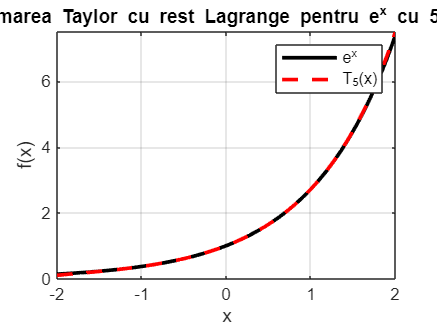



% Convertim expresia simbolică într-o funcție MATLAB
T5_func = matlabFunction(T5, 'Vars', x);

% Plotăm funcția originală și aproximarea Taylor
figure
fplot(f, [-2, 2], 'k', 'LineWidth', 2) % Funcția exactă e^x
hold on
fplot(T5_func, [-2, 2], 'r--', 'LineWidth', 2) % Aproximarea Taylor
legend('e^x', ['T_', num2str(N), '(x)'])
title(['Aproximarea Taylor cu rest Lagrange pentru e^x cu ', num2str(N), ' termeni'])
xlabel('x'); ylabel('f(x)')
grid on